# Practicum Control Theory 1 – Q1 Week 5-6

*Requirements: Matlab R2018a or higher with the Control Systems Toolbox.*

These weeks we start to use the Control System Toolbox with some functions to describe the transfer function of a system in the s-domain, represent it in a pole-zero plot and compute the pulse and unit step responses. 

## Describe a system

To describe a system, we describe the system in the s-domain by providing the transfer function such as

$H(s) = \frac{s^2+3s+2}{s^4+4s^3+6s^2+3s+2}
$.

In Matlab, this transfer function can be defined as

H = tf([1 3 2],[1 4 6 3 2]);

where `tf` is the function to create the transfer function model. The first argument provides the constants for each $s^n$ term for the nominator, while the second argument provides the constants for the denominator. 

To draw the pole-zero plot for this transfer function, the Control System Toolbox has the option `pzplot(H)`. Instead, you can actually convert the transfer function into the zero-pole-gain representation by using the `zpk(H)` function. If you call

h = zpk(H)


h =
 
                   (s+2) (s+1)
  ---------------------------------------------
  (s^2 + 0.3003s + 0.4506) (s^2 + 3.7s + 4.438)
 
Continuous-time zero/pole/gain model.



the output will be 

`h =`

                   `(s+2) (s+1)`

  `---------------------------------------------`

  `(s^2 + 0.3003s + 0.4506) (s^2 + 3.7s + 4.438)`

where you do not recognize the pole zero gain representation yet. But the variable `h` is an object now and stores also the zeros `h.z`, poles `h.p` and the gain factor `h.z`. You can access these outputs by using the following code:

h.z{:}

ans =     -2
    -1


h.p{:}

ans =   -1.8498 + 1.0082i
  -1.8498 - 1.0082i
  -0.1502 + 0.6543i
  -0.1502 - 0.6543i


h.k

ans = 1

The `h` object is another system representation, but can be used as input for `pzplot `just the same. In a similar way, you can define the transfer function in terms of the poles and zeroes. Check out the help of `zpk` to find out out how to include the zeros, poles and gain factor.

As both the transfer function as the pole-zero plot are representations of the same system, both system representations can be used to find the impulse response or unit step response. Also for this the Control System Toolbox has the `stepplot` and `impulseplot `function to draw the unit step response and the impulse response.

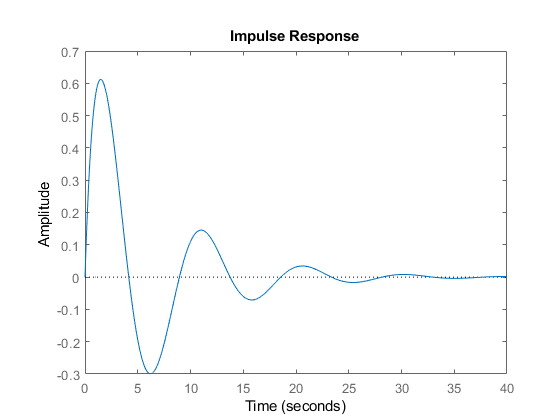

impulseplot(H)

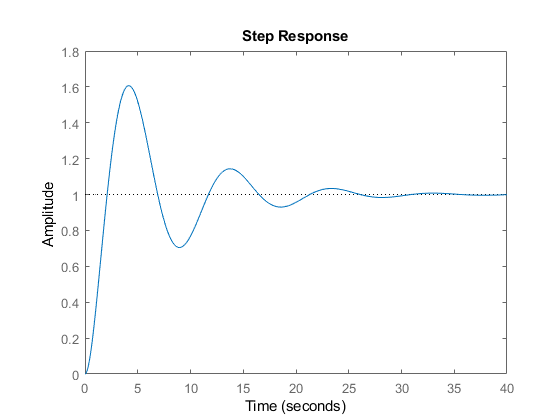

stepplot(H)

 Please study the help documentation on the commands `tf`, `pzplot`, `zpk`, `stepplot` and `impulseplot` to find out about the details of each one of them.

### **Assignment 1: system description**

*For each of the transfer functions shown below:*

- *find the locations of the poles and zeros*

- *plot them in a pole-zero plot*

- *calculate the impulse and step response using Laplace transform techniques and *

- *plot these responses.*

- 
$$T_{1}(s) = \frac{2}{s+2}$$


- 
$$T_{2}(s) = \frac{5}{(s+3)(s+6)}$$


- 
$$T_{3}(s) = \frac{10(s+7)}{(s+10)(s+20)}$$


- 
$$T_{4}(s) = \frac{20}{s^2+6s+144}$$


- 
$$T_{5}(s)=\frac{s+2}{s^2+9}$$


- 
$$T_{6}(s) = \frac{s+5}{(s+10)^{2}}
$$


*Verify your answers using the Control Systems Toolbox by comparing the figures for the pole-zero plot (*`pzplot`*), impulse response (*`impulseplot`*) and the unit step response (*`stepplot`*).*

*State the nature of each response (overdamped, underdamped, etc.) if applicable.*

Next, we use the Control System Toolbox to analyze the unit step response and the natural response (pulse response) of the system. The Control System Toolbox has several ways to define the system, e.g. the `tf`function to create the transfer function model or with the `zpk` function to create the zero-pole-gain representation of this system. Both ways were already illustrated in last week’s assignment. The focus of this week is to find the characteristics of the transient response of the system, such as the rise time, settling time, peak time and percentage overshoot.

## Find the characteristics of a system

To describe a system, we describe the system in the s-domain by providing the transfer function

$H(s) = \frac{1}{s^2+4s+20}$. 

In Matlab, this transfer function can be defined as

H = tf(1,[1 4 20]);

If the zero-pole representation is required, for example to identify what kind of system you have, you can actually convert the transfer function into the zero-pole-gain representation by using the `zpk(H)` function. If you call

h = zpk(H)

the output will have information about the poles, zero and gain (call `h.z{:}` for the zeros, `h.p{:} `for the poles and `h.k` for the gain).

The Control System Toolbox has a command to analyze a system in a GUI environment, namely `linearSystemAnalyzer(sys)`, where `sys` is the system, which can either be in transfer function notation (`H` in our case) or in zero-pole-gain notation (`h` in our case). If you call this command, you will get the result of Figure 1.

If you right-click your mouse, you see the Plot Types, where you can display the step response (Step), pulse response (Impulse), pole-zero plot (Pole/Zero). This option menu is displayed in Figure 2 (left). This week’s main focus is to find the characteristics from the step response. Again, if you right-click your mouse, you see Characteristics, where you can display the peak response, settling time, rise time and steady state (see Figure 2 (right)).

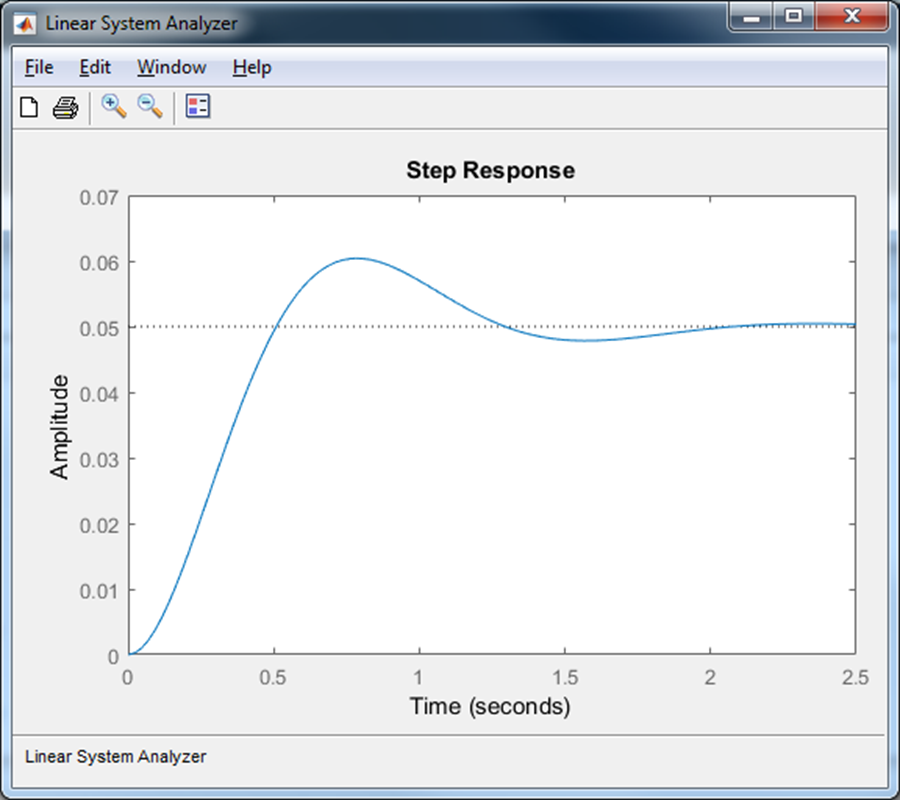*.Figure 1 Screenshot of linearSystemAnalyzer(sys)*

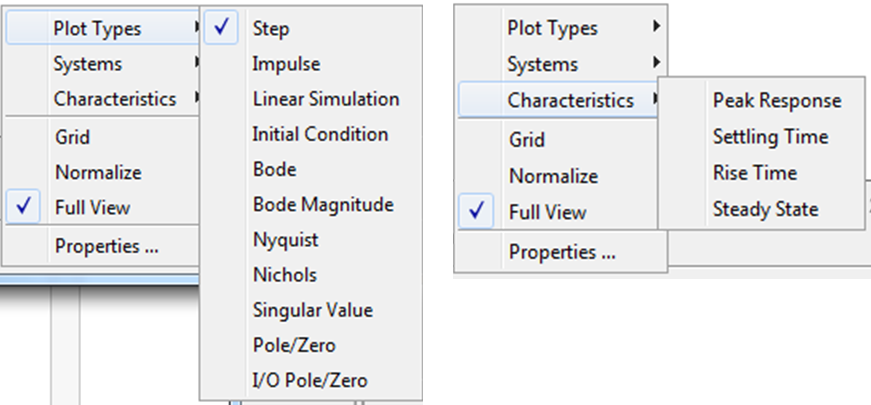

*Figure 2 Option menus*

Please study the help documentation on the commands `tf`, `zpk` and `linearSystemAnalyzer` to find out about the details of each one of them.

### **Assignment 2: Characteristics of system**

*Determine for each of the transfer functions shown below, if the system is overdamped, underdamped, undamped, or critically damped by finding the locations of the poles and by calculating the damping ratio and the natural frequency. Finally, find the characteristics (peak time, percentage overshoot, rise time, settling time and steady state) for each of the unit step responses, if applicable.*

- 
$$T_{1}(s) = \frac{5}{s^2+9s+18}$$


- 
$$T_{2}(s) = \frac{20}{s^{2}+6s+144}$$


- 
$$T_{3}(s) = \frac{16}{s^2+3s+16}$$


- 
$$T_{4}(s) =\frac{3}{s^2+4}$$


- 
$$T_{5}(s) = \frac{3}{s^2+2s+1}$$


- 
$$T_{6}(s) = \frac{0,04}{s^2+0,02s+0,04}$$


*Verify your answers using the Control Systems Toolbox by using the *`linearSystemAnalyzer`* GUI.*

### **Assignment 3: Characteristics of a system**

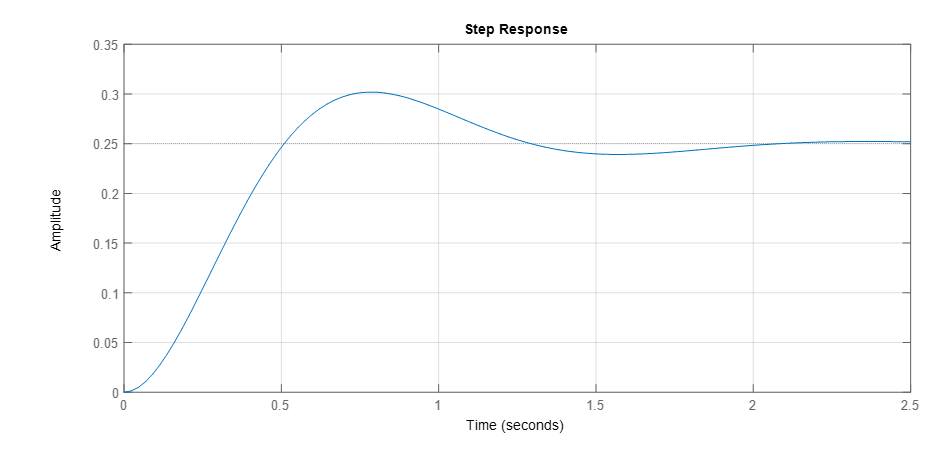

*Determine the transfer function of the system with the step response as shown in the figure above. This figure is available on N@tschool under the name *`Plot_CT1_week5_6_Ass3.fig`*.*

*Check your answer with the Control System Toolbox of Matlab.*